Name: Yusu (Cosmo) Zhao

Student Number: 20761282

PartA:

My design will have 6 joints: RPRPRR.  The design diagram is as follows. The initial position of this robot is at x=0.3 z=0.2, so that the robot is right behind the cuboid at the beginning (in terms of the x-axis direction). With the limitation of the third joint, the paddle will only face the front to hit the ball. In other words, the paddle should always be the farthest point from the origin in terms of the x-axis. From this begining point, we want to cover every point in the cuboid. I added two prismatic joint to extend the arm. The farthest distance from the starting point to any point in the cuboid is the distance from the starting point to the point A or B below. This distance is given by the square root of $\sqrt{\;0\ldotp 8^2 +0\ldotp 8^2 +0\ldotp 5^2 }\approx 1\ldotp 237>1$. Since the limit of prismatic joint is one meter, one prismatic joint is not able to handle it. To move along x-axis, we added the joint 1 to support rotation. However, we want our paddle to be perpendicular to the ground, so I also added the joint 5 to cancel the angle brought by theta one. For similar reason I added the joint 3 and 6 because we want to move in the y-axis direction and make our paddle always face the front (with some range). So roughly speaking, joint 1 and 5 are responsible for movement in z direction, and joint 3 and 6 are responsible for movement in the y direction, and joint 2 and 4 are responsible for the movement in the x direction, but it will also help to precisly locate the end effector. 

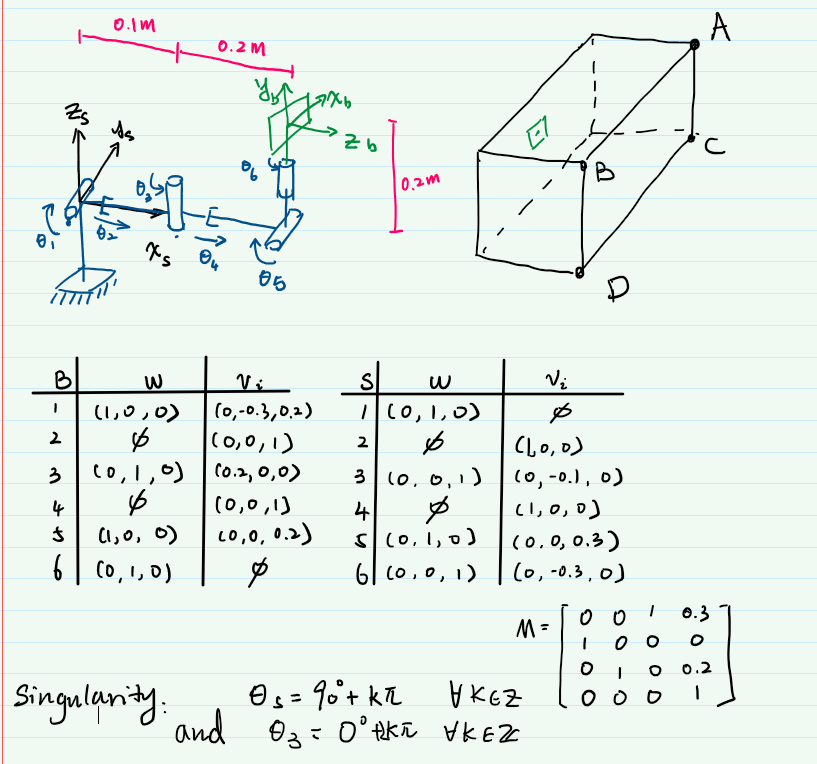

PartB:

-  The joint types, [S], [B], and M are obtained from the part A. We calculated the twist of each joint at their zero position. I am also taking the maximum value of joints (2 pi range for rotation joint and 0-1 for prismatic) to ensure that we can cover the task space. These code can be used to calculate the forward kinematics of the end effector, and the manipubility of the end effector. For example, these screw axis can be used to calculate the jacobian matrices later, and calculate the inverse kinematics. 

% Add the MATLAB library provided by http://modernrobotics.org
unzip('mr.zip');

% Define joint_types, joint_limits, S_list, B_list, and M
joint_types = ['R','P','R','P','R','R']; % the types of joints you have using a row vector of 'R' and 'P' elements
n_joints = length(joint_types);
joint_limits = [[-pi/2;pi/2],[0;1],[-pi/2;pi/2],[0;1],[-pi;pi],[-pi;pi]]; % must have the dimensions [2, n_joints]

S_list = [[0;1;0;0;0;0],[0;0;0;1;0;0],[0;0;1;0;-0.1;0],[0;0;0;1;0;0],[0;1;0;0;0;0.3],[0;0;1;0;-0.3;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
B_list = [[1;0;0;0;-0.3;0.2],[0;0;0;0;0;1],[0;1;0;0.2;0;0],[0;0;0;0;0;1],[1;0;0;0;0;0.2],[0;1;0;0;0;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
M = [[0,0,1,0.3];[1,0,0,0];[0,1,0,0.2];[0,0,0,1]]; % must be in SE(3)

2.  To calculate the manipulability ellipsoid, I will use the Jacobian for angular vecocity and linear velocity separately by taking the first three rows or the last three rows of the Jacobian matrix. And the methods I am using are pretty similar. Let's take the angular ellipsoid as an example. We first grab the first three rows of J_B to form the angular Jacobian, and then I calculate the A matrix by mutiplying the angular Jacobian by its transpose. Then, I calculate the eigenvectors and eigenvalues of the matrix A. The eigenvectors will be used as the rotation matrix of the ellipsoid, and we use the matrix logrithm to calculate the so3 and finally decompose it to the rotation axis and angles. Because there is no guarantee that the calculated eigenvalue matrix is in the right-hand system, we will do an additional check, and if the matrix is not right-handed, we just swap the first two columns. We then take the square root of the eigenvalues to calculate the semi-axis lengths. We do the similar thing to get the linear ellipsoid. Then, we follow the formula on the textbook to calculate the thre mu values. Finally, we use mu3 to decide if the whole system is at singularity. When mu3 is small enought to zero (to eliminate the rounding error), we would say that the system is at singularity. 

This function can be useful later when we calculate the inverse kinematics and the trajectory as we need to be aware of the singularities of the system in those calculations, and pay more attention to those singularites. 

% Add the MATLAB library provided by http://modernrobotics.org
unzip('mr.zip');

% Include the joint_types, joint_limits, and B_list for your robot from the Robot Design problem
B_list = [[1;0;0;0;-0.3;0.2],[0;0;0;0;0;1],[0;1;0;0.2;0;0],[0;0;0;0;0;1],[1;0;0;0;0;0.2],[0;1;0;0;0;0]]; 
joint_types = ['R','P','R','P','R','R'];
joint_limits = [[-pi/2;pi/2],[0;1],[-pi/2;pi/2],[0;1],[-pi;pi],[-pi;pi]];

% Include the location of any singularities in your robot's kinematic space as columns in a matrix
singularities = [[0;0;0;0;0;0], [0;0;0;0;pi/2;0], [0;0;0;0;-pi/2;0]];

manipFun = @manipulability;
% Fill in the function template below to satisfy the problem outline above

function [at_singularity, mu_angular, mu_linear] = manipulability(J_B, thetalist)
% Inputs:
% J_B - the Body Jacobian matrix for an arbitrary robot
% thetalist - a list of joint positions for the robot

% Determine and plot the linear and angular manipulability ellipsoids
J_w = J_B(1:3, :);
J_v = J_B(4:6, :);

% Calculate the ellipsoid for angular
A_w = J_w * J_w.';                                % Grab the A matrix
[eig_vecs_w, eig_vals_w] = eig(A_w);              % Calculate the eigenvalues and eigenvectors
if det(eig_vecs_w) < 0                            % No gurantee that eig_vecs is a right hand system, so check it
    eig_vecs_w = eig_vecs_w(:,[2,1,3]);           % Swap columns if it is not a valid right hand frame
end
[rotation_axis_w, rotation_angle_w] = AxisAng3(so3ToVec(MatrixLog3(eig_vecs_w))); % Use the eigen vectors as the rotation matrix to calculate the angles
% Draw the ellipsoid
figure(1)
[x_w, y_w, z_w] = ellipsoid(0,0,0,sqrt(eig_vals_w(1,1)),sqrt(eig_vals_w(2,2)),sqrt(eig_vals_w(3,3)));
S_w = surfl(x_w, y_w, z_w);
rotate(S_w, rotation_axis_w, rotation_angle_w)
title("Angular Manipulability Ellipsoid")
axis equal

A_v = J_v * J_v.';
[eig_vecs_v, eig_vals_v] = eig(A_v);
if det(eig_vecs_v) < 0
    eig_vecs_v = eig_vecs_v(:,[2,1,3]);
end
[rotation_axis_v, rotation_angle_v] = AxisAng3(so3ToVec(MatrixLog3(eig_vecs_v)));
figure(1)
[x_v, y_v, z_v] = ellipsoid(0,0,0,sqrt(eig_vals_v(1,1)),sqrt(eig_vals_v(2,2)),sqrt(eig_vals_v(3,3)));
S_v = surfl(x_v, y_v, z_v);
rotate(S_v, rotation_axis_v, rotation_angle_v)
title("Linear Manipulability Ellipsoid")
axis equal

% Calculate the measures mu_1, mu_2, and mu_3 for both linear and angular motion
% Transform the eigen values from the diagonal matrix
eig_w = diag(eig_vals_w);
eig_v = diag(eig_vals_v);
% Calculate the mus
mu_angular = [sqrt(max(eig_w)/min(eig_w)), max(eig_w)/min(eig_w), sqrt(prod(eig_w))];
mu_linear = [sqrt(max(eig_v)/min(eig_v)), max(eig_v)/min(eig_v), sqrt(prod(eig_v))];

% Determine if the given thetalist places the robot in a singularity
% at_singularity = 1 if at a singularity, 0 otherwise
% Calculate the mu3 of J_B
A = J_B * J_B.';
at_singularity = double(sqrt(det(A)) < 10e-5);

end